This script loads epoched EEG data in eeglab data structure, and saves only the data (electrodes x timepoints) and event matricies

folder = fileparts(which('C:\Users\User\Cloud-Drive\AnatArzi\eeglab2022.1\functions')); 
addpath(genpath(folder));

import_type ='eventDetection11Electrodes_plainEEGLAB';
preproc_name =  'preProcessed'; %'imported';

input_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid';
output_dir = strcat('C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\',preproc_name,'_',import_type,'\');

wake_files_name_suffix = strcat('_wake_night_',preproc_name,'.set');

% electrodes = 1:93;
% electrodes = [5,6,11,80,85]; %% in MNE-python they are [4,5,10,79,84]
% electrodes = [7,17,29,76,52,61,91]; %% in preProcessed(after mastoid ref)[E9,E22,E36,E104,E70,E83,Cz]
electrodesNames = {'E9','E22','E36','E104','E70','E83','E24','E124','E52','E92','Cz'}; %% E22,E9=Fp1,Fp2    E36,E104=C3,C4    E70,E83=O1,O2,  E24,E124=F3,F4,    E52,E92=P3,P4
%electrodes = [1,32,124,125,127];  %%%  In "imported" after referencing to masotid: EMG1/2 are 126,127 and EOGL/R are 32,1 cz is 127

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
subs = {'31','32','33','34','35','38'};

for sub_ind=1:size(subs,2)
    for sleepFileNum=1:6
        sleep_files_name_suffix = strcat('_sleep',num2str(sleepFileNum),'_',preproc_name,'.set');
        output_filename = strcat(output_dir,'sub',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_', preproc_name, '_',import_type,'.mat');
        if isfile(output_filename)
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end

        try
            if preproc_name=='preProcessed'
                set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_preProcessed.set');
            elseif preproc_name=='imported'
                set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_orig.set');
            else
                'no such preproc_name'
                continue
            end
            eeglabsub_sleep =  pop_loadset(set_filename, input_dir);


            %% find all labels
            all_labels = {eeglabsub_sleep.chanlocs.labels};
            electrodesNumber =[];
            for label_ind=1:size(all_labels,2)
                if any(ismember(electrodesNames, all_labels(label_ind)))
                    electrodesNumber(end+1) = label_ind;
                end
            end
            if size(electrodesNames,2) > size(electrodesNumber,2) 
                'didnt find all electrodes labels' 
            end
                

            subEvents = eeglabsub_sleep.event;
            subData = eeglabsub_sleep.data;
            subData = subData(electrodesNumber,:);
            samplefreq = eeglabsub_sleep.srate;

            if ~isfolder(output_dir)
                mkdir(output_dir)
            end
            save(output_filename{1},"subEvents","subData","samplefreq",'electrodesNames');
        catch ME
            continue
        end 
    end
end

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep1_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep2_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep3_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep4_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep5_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_31_sleep6_preProcessed.set ...


ans = "Sub_32 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub32_sleep1_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_32 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub32_sleep2_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_32 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub32_sleep3_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_32_sleep4_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_32_sleep5_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_32_sleep6_preProcessed.set ...


ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub33_sleep1_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub33_sleep2_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub33_sleep3_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub33_sleep4_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_33_sleep5_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_33_sleep6_preProcessed.set ...


ans = "Sub_34 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub34_sleep1_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_34 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub34_sleep2_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_34 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub34_sleep3_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_34_sleep4_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_34_sleep5_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_34_sleep6_preProcessed.set ...


ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub35_sleep1_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub35_sleep2_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub35_sleep3_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_eventDetection7Electrodes_plainEEGLAB\sub35_sleep4_preProcessed_eventDetection7Electrodes_plainEEGLAB.mat"

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_35_sleep5_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_35_sleep6_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_38_sleep1_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_38_sleep2_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_38_sleep3_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_mastoid\s_38_sleep4_preProcessed.set ...
pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\preProcessed_reference_to_masto

basename = 1×79 cell array
    {'s_01_sleep1'}    {'s_01_sleep2'}    {'s_01_sleep3'}    {'s_02_sleep1'}    {'s_02_sleep2'}    {'s_03_sleep1'}    {'s_03_sleep2'}    {'s_04_sleep1'}    {'s_04_sleep2'}    {'s_06_sleep1'}    {'s_06_sleep2'}    {'s_06_sleep3'}    {'s_06_sleep4'}    {'s_07_sleep1'}    {'s_07_sleep2'}    {'s_07_sleep3'}    {'s_08_sleep1'}    {'s_08_sleep2'}    {'s_08_sleep3'}    {'s_08_sleep4'}    {'s_08_sleep5'}    {'s_09_sleep1'}    {'s_09_sleep2'}    {'s_09_sleep3'}    {'s_10_sleep1'}    {'s_10_sleep2'}    {'s_10_sleep3'}    {'s_10_sleep4'}    {'s_11_sleep1'}    {'s_11_sleep2'}    {'s_11_sleep3'}    {'s_12_sleep1'}    {'s_12_sleep2'}    {'s_13_sleep1'}    {'s_13_sleep2'}    {'s_13_sleep3'}    {'s_13_sleep4'}    {'s_14_sleep1'}    {'s_14_sleep2'}    {'s_14_sleep3'}    {'s_14_sleep4'}    {'s_14_sleep5'}    {'s_15_sleep1'}    {'s_15_sleep2'}    {'s_15_sleep3'}    {'s_16_sleep1'}    {'s_16_sleep2'}    {'s_16_sleep3'}    {'s_16_sleep4'}    {'s_17_sleep1'}    {'s_17_sleep2'}    

## Use of Anat's code to extract and preprocess orig data for scoring

addpath C:\Users\User\Cloud-Drive\AnatArzi\eeglab2022.1

import_type ='eventDetectionChan';
preproc_name =  'imported';

input_dir = 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported';
output_dir = strcat('C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\',preproc_name,'_',import_type,'\');

wake_files_name_suffix = strcat('_wake_night_',preproc_name,'.set');

electrodesNames =     {'E127',  'E94','E126', 'E1', 'E31', 'E9','E22','E36','E104','E70','E83','E24','E124','E52','E92','Cz'}; 
electrodesPSG_names = {'EMG1', 'EMG2','EMG3', 'LOC','ROC', 'Fp1','Fp2','C3','C4',  'O1',  'O2','F3',  'F4', 'P3', 'P4', 'Cz'};
subs = {'32','33','34','35','38'};
subs = {'35'}

subs = 1×1 cell array
    {'35'}


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 to the path
EEGLAB: adding "clean_rawdata" v2.7 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.5.1 (see >> help eegplugin_firfilt) - new version 2.6 available


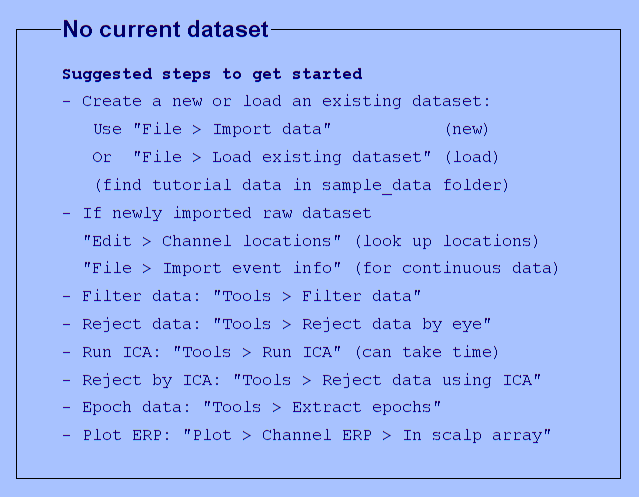

You are using the latest version of EEGLAB.


[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

if ~isfolder(output_dir)
    mkdir(output_dir)
end

for sub_ind=1:size(subs,2)
    for sleepFileNum=1:6
        sleep_files_name_suffix = strcat('_sleep',num2str(sleepFileNum),'_',preproc_name,'.set');
        output_filename = strcat('sub',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_', preproc_name, '_',import_type);
        output_filename = output_filename{1};
        if isfile([output_dir output_filename '.set']) && isfile([output_dir output_filename '.mat']) && isfile([output_dir output_filename '.bdf'])
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end

        set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_orig.set');
        set_filename = set_filename{1};
        if ~isfile([input_dir '\' set_filename])
            ['no input file ' input_dir set_filename]
            continue
        end
        try
            EEG =  pop_loadset(set_filename, input_dir);
            [ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );
            EEG = eeg_checkset(EEG);
        catch ME
            ['error uploading ' input_dir set_filename]
            continue
        end 

        % reref to mastoid
        EEG = rereferenceFullNightSleep(EEG,3); %3 = linked mastoid
            
        % get labels and change thire names 
        all_labels = {EEG.chanlocs.labels};
        electrodesNumber =[];
        for label_ind=1:size(all_labels,2)
            if any(ismember(electrodesNames, all_labels(label_ind)))
                electrodesNumber(end+1) = label_ind;
            end
        end
        if size(electrodesNames,2) > size(electrodesNumber,2) 
            'didnt find all electrodes labels' 
        end
        [EEG.chanlocs(1,electrodesNumber).labels] = deal(electrodesPSG_names{:});
                    
        % exclude all electrode but the ones listed in loc
        chanexcl = 1:size(all_labels,2);
        chanexcl(electrodesNumber) = [];
        EEG = pop_select(EEG,'nochannel',chanexcl);
        
        % For EEG electrods
        lpfreq = 45;
        fprintf('Low-pass filtering above %dHz...\n',lpfreq);
        EEG40 = pop_eegfiltnew(EEG, [], lpfreq, 66, 0, [], 0);
        hpfreq = 0.3;% % (Anat's PSG was 0.5)
        fprintf('High-pass filtering EEG below %dHz...\n',hpfreq);
        EEG_filt05 = pop_eegfiltnew(EEG40, [], hpfreq, 8500, true, [], 0);% EEG electrodes
        
        % For EMG electrodes
        hpfreq = 20;
        fprintf('High-pass filtering EOG below %dHz...\n',hpfreq);
        EEG_filt20 = pop_eegfiltnew(EEG, [], hpfreq, 8500, true, [], 0);
        EEG_filt05.data([1,2,3],:) = EEG_filt20.data([1,2,3],:);% EMG electrodes 
        
        % For EOG electrodes
        lpfreq = 2;
        fprintf('EOG Low-pass filtering above %dHz...\n',lpfreq);
        EEG_filt2 = pop_eegfiltnew(EEG, [], lpfreq, 8500, 0, [], 0);
        hpfreq = 0.1;
        fprintf('EOG High-pass filtering EOG below %dHz...\n',hpfreq);
        EEG_filt01 = pop_eegfiltnew(EEG_filt2, [], hpfreq, 8500, true, [], 0);% eye electrodes
        EEG_filt05.data([4,5],:) = EEG_filt01.data([4,5],:);% eye electrodes 
        
%             EEG_filt05.data([3,4,5,7],:) = EEG_filt05.data([3,4,5,7],:)*0.7; % O1 and O2          
%             EEG_filt05.data(6,:) = EEG_filt05.data(6,:)*0.1;
        
        EEG = EEG_filt05;

        %% savings
        % save .set
        [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off');
        EEG = pop_saveset(EEG, 'filename',[output_filename],'filepath',output_dir);
        % save .bdf
        pop_writeeeg(EEG, [output_dir output_filename '.bdf'],'TYPE','BDF'); %% no other intersting parameters.
        % save .mat
        subEvents = EEG.event;
        subData = EEG.data;
        samplefreq = EEG.srate;
        chansNames  = electrodesPSG_names;
        save([output_dir, output_filename '.mat'],"subEvents","subData","samplefreq",'chansNames');
    end
end

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_35_sleep1_orig.set ...


Creating a new ALLEEG dataset 1


Referencing to E57E100.
Re-referencing data


Removing 111 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.3 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.202941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EOG below 20Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 20 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 19.9029411764706 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG Low-pass filtering above 2Hz...


pop_eegfiltnew() - performing 8501 point lowpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 2.09705882352941 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG High-pass filtering EOG below 1.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.00294117647058825 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 2


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.197021e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 6.526620e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 180 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_35_sleep2_orig.set ...


ans = 'error uploading C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\importeds_35_sleep2_orig.set'

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_35_sleep3_orig.set ...


Creating a new ALLEEG dataset 3


Referencing to E57E100.
Re-referencing data


Removing 111 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.3 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.202941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EOG below 20Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 20 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 19.9029411764706 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG Low-pass filtering above 2Hz...


pop_eegfiltnew() - performing 8501 point lowpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 2.09705882352941 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG High-pass filtering EOG below 1.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.00294117647058825 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 4


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.064994e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 4.034646e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 120 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_35_sleep4_orig.set ...


Creating a new ALLEEG dataset 5


Referencing to E57E100.
Re-referencing data


Removing 111 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.3 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.202941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EOG below 20Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 20 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 19.9029411764706 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG Low-pass filtering above 2Hz...


pop_eegfiltnew() - performing 8501 point lowpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 2.09705882352941 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EOG High-pass filtering EOG below 1.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.00294117647058825 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 6


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.029596e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 3.793964e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 108 NaNs added to complete data block.


ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\importeds_35_sleep5_orig.set'

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\importeds_35_sleep6_orig.set'